## Exercicio 2

Vdc=RT030_SetPressure(0.6);

ans = 'Press?o: 0.0410376'

ans = 'Tens?o: 1.1'

ans = 'Press?o: 0.0436844'

ans = 'Tens?o: 1.2'

ans = 'Press?o: 0.0370674'

ans = 'Tens?o: 1.3'

ans = 'Press?o: 0.0317739'

ans = 'Tens?o: 1.4'

ans = 'Press?o: 0.0926502'

ans = 'Tens?o: 1.5'

ans = 'Press?o: 0.116471'

ans = 'Tens?o: 1.6'

ans = 'Press?o: 0.138969'

ans = 'Tens?o: 1.7'

ans = 'Press?o: 0.172054'

ans = 'Tens?o: 1.8'

ans = 'Press?o: 0.21308'

ans = 'Tens?o: 1.9'

ans = 'Press?o: 0.226313'

ans = 'Tens?o: 2'

ans = 'Press?o: 0.295082'

ans = 'Tens?o: 2.1'

ans = 'Press?o: 0.338457'

ans = 'Tens?o: 2.2'

ans = 'Press?o: 0.357047'

ans = 'Tens?o: 2.3'

ans = 'Press?o: 0.401971'

ans = 'Tens?o: 2.4'

ans = 'Press?o: 0.437601'

ans = 'Tens?o: 2.5'

ans = 'Press?o: 0.465223'

ans = 'Tens?o: 2.6'

ans = 'Press?o: 0.577363'

ans = 'Tens?o: 2.61'

ans = 'Press?o: 0.591207'

ans = 'Tens?o: 2.62'

ans = 'Acabou com 2.62 tens???o e 0.59 press???o na camara.'


V=0.5; % Naõ acionar a valvula dos 0.8 nem ultrapassar os limites 0/5 V
fa=50;           %fa>=2*freq(sinal max)
fk=[fa/100 fa/200 fa/500 fa/1000 fa/2000]; %(Hz)
T=1./fk

T =      2     4    10    20    40


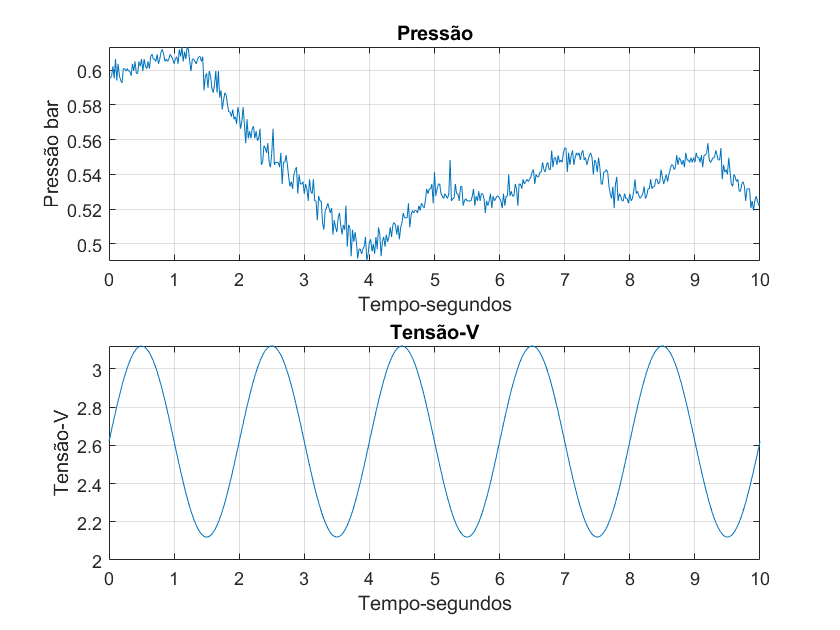

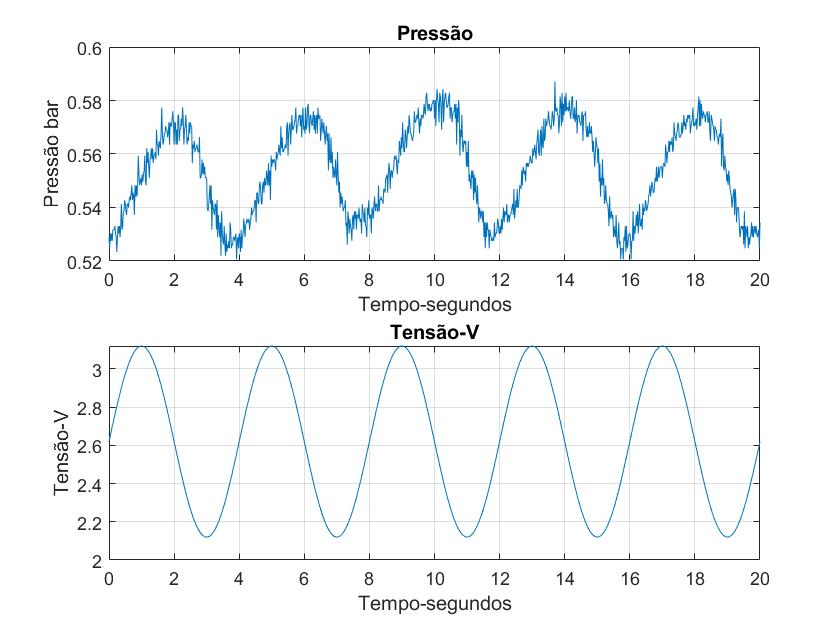

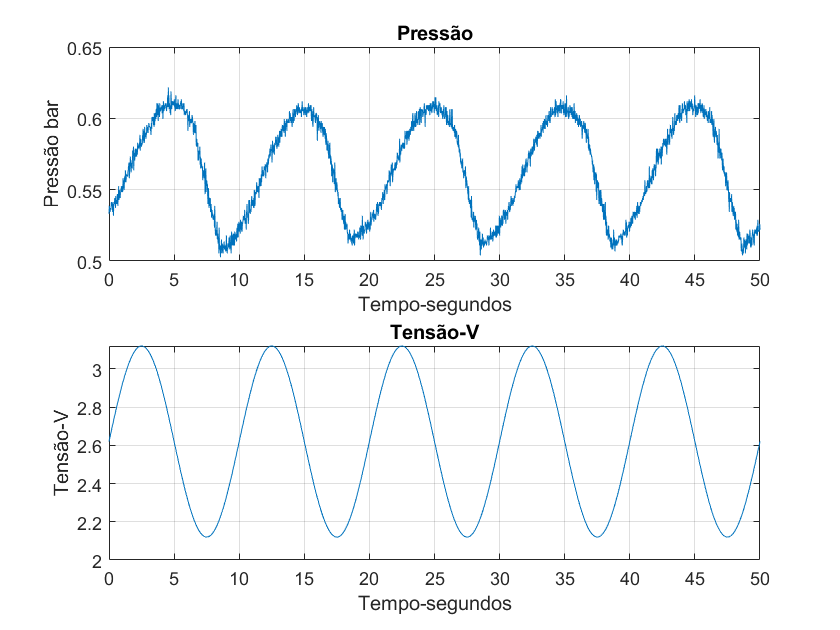

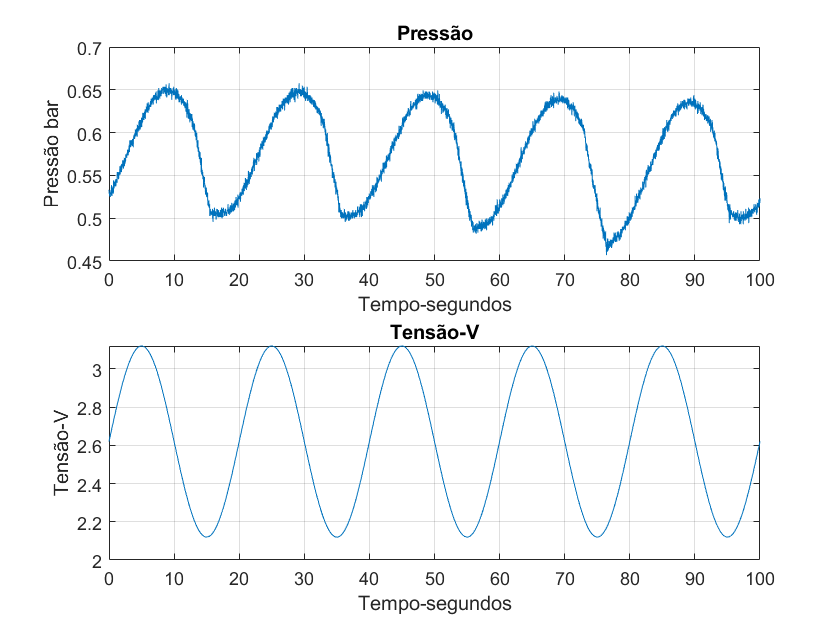

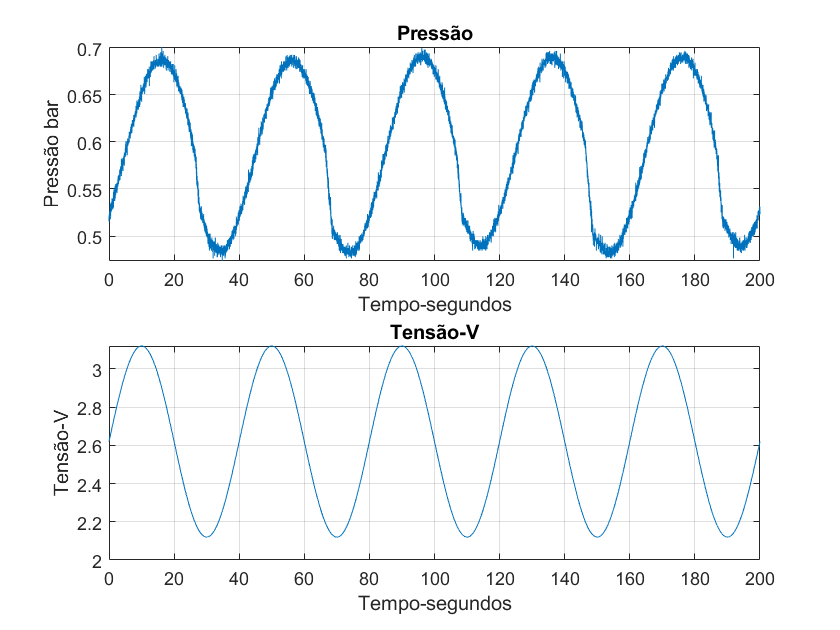

for i=1:length(fk)
    tempomax=0;
    aux=0;
    max=0;
    press=0;
    tens=0;
    t=0:1/fa:5*T(i); %5 periodos
    
    for j=1:length(t)
        volt=Vdc+V*sin(2*pi*fk(i)*t(j));
        RT030_SetCompressorVoltage(volt);
        PressV=RT030_GetPressure;
        press(j)=PressV(1);
        tens(j)=volt;
        if(t(j)<=T(i))
            if(press(j)>max)
                max=press(j);
                tempomax=t(j);
            end
            aux(j)=press(j);
        end
    end
    tempotens=T(i)/4;
    media(i)=mean(aux);
    amplitude(i)=abs(max-media(i));
    atraso(i)=tempomax-tempotens;
    phase(i)=(atraso(i)*360)/T(i); %Cálculo da fase
    %gráficos de tensão e da pressão ,para cada valor da frequencia
    figure(i);
    subplot(211);
    plot(t,press);
    title('Pressão');
    xlabel("Tempo-segundos");
    ylabel("Pressão bar");
    grid on;
    subplot(212);
    plot(t,tens);
    title('Tensão-V');
    xlabel("Tempo-segundos");
    ylabel("Tensão-V");
    grid on;
end


ganho=amplitude./V;     %calculo do ganho
ganhodB=20*log10(ganho);%calculo do ganho em dbs

figure;
%Gráfico do ganho 
subplot(211);
semilogx(fk,ganhodB);   % curva experimental
hold on
Pg=polyfit(fk,ganhodB,1)

Pg =   -34.7023  -14.4887


ganho_teo=Pg(1).*fk+Pg(2);
semilogx(fk,ganho_teo,'--') %Curva teorica
title('Ganho');
xlabel('Frequencia-Hz');
ylabel('Ganho-dB');
grid on;

%gráfico da fase
subplot(212);
semilogx(fk,phase);
hold on
Pf= polyfit(fk,phase,2)

Pf =   449.7906 -151.6050   73.4903


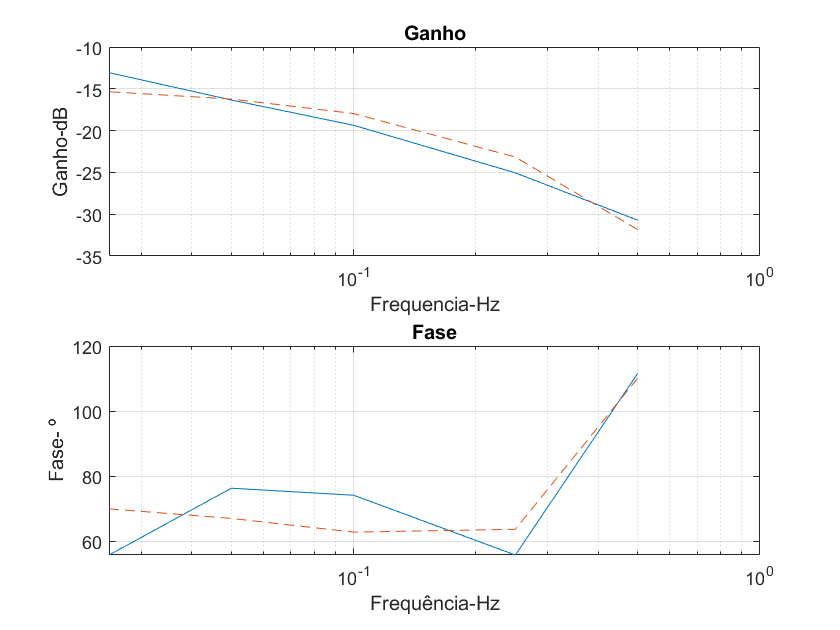

phase_teo= Pf(1).*fk.^2+Pf(2).*fk+Pf(3);
semilogx(fk,phase_teo,'--')                 %Curva teorica
title('Fase');
xlabel('Frequência-Hz');
ylabel('Fase- º');
grid on